%% Nettoyage de l’environnement
clear all; close all; clc;
run("C:\Users\33676\Documents\tictac\MATLAB\cardiometre\battement7.m");  % Exécuter le script pour charger la variable bat

# Mesure des battements cardiaques par PPG

## Nettoyage de l'environnement

Cette section initialise l'environnement MATLAB en effaçant toutes les variables existantes (`clear all`), en fermant toutes les figures ouvertes (`close all`) et en vidant la fenêtre de commande (`clc`). Elle charge ensuite le script `battement8.m` qui contient les données de battements cardiaques mesurées par photopléthysmographie (PPG) dans la variable `bat`. Cette étape de préparation est essentielle pour garantir que la mesure des battements cardiaques se déroule dans un environnement propre, sans interférence avec d'éventuelles variables ou figures précédentes.

## 1) Construction de l'axe temporel

Cette rubrique établit l'axe temporel du signal de battements cardiaques. La fréquence d'échantillonnage est définie à 500/7 Hz (environ 71.4 Hz), ce qui correspond à la fréquence d'acquisition des données PPG de votre capteur cardiaque. Le nombre total d'échantillons N est déterminé par la longueur du signal `bat`. L'axe temporel `t` est alors construit en divisant chaque indice d'échantillon par la fréquence d'échantillonnage, permettant ainsi de convertir les indices en unités de temps (secondes). Cette conversion est cruciale pour l'analyse temporelle et la mesure précise des battements cardiaques.

## 2) Filtrage passe-bande (0,5–5 Hz)

Le filtrage passe-bande est appliqué pour isoler les composantes fréquentielles correspondant aux battements cardiaques dans le signal PPG. Les fréquences de coupure sont fixées à 0.5 Hz (fréquence basse) et 5 Hz (fréquence haute), ce qui correspond à la plage physiologique des battements cardiaques humains (30 à 300 bpm). Un filtre de Butterworth d'ordre 3 est utilisé pour sa réponse plate dans la bande passante. La fonction `filtfilt` applique un filtrage bidirectionnel, éliminant le déphasage et doublant l'ordre effectif du filtre. Ce filtrage supprime les bruits basse fréquence (mouvements, dérive du capteur) et haute fréquence (parasites électriques) qui pourraient perturber la mesure des battements cardiaques.

## 3) Détection des pics (battements)

Cette section implémente l'algorithme de détection des battements cardiaques. Le seuil de détection est calculé automatiquement comme la moyenne du signal filtré plus 0.5 fois son écart-type, permettant une adaptation au niveau du signal. La distance minimale entre deux pics est fixée à 0.4 seconde, correspondant à une fréquence cardiaque maximale de 150 bpm, évitant ainsi la détection de faux positifs. La fonction `findpeaks` identifie les maxima locaux du signal filtré qui dépassent le seuil et respectent la contrainte de distance minimale. Les positions temporelles et les amplitudes des pics détectés sont stockées dans `locs` et `peaks` respectivement.

## 4) Calcul de la Fréquence Cardiaque Instantanée

Cette rubrique calcule la fréquence cardiaque instantanée à partir des intervalles entre battements consécutifs. Les intervalles inter-battements (IBI) sont calculés en prenant la différence entre les positions temporelles des pics successifs. La fréquence cardiaque instantanée est alors obtenue en divisant 60 par chaque IBI, convertissant les intervalles en secondes vers une fréquence en battements par minute (bpm). L'axe temporel correspondant `t_HR` est défini aux positions des deuxièmes pics de chaque paire, permettant de tracer l'évolution temporelle de la fréquence cardiaque.

## 5) Affichages

Cette section génère trois visualisations essentielles pour l'analyse du signal PPG :

**Signal brut vs signal filtré** : La première figure compare le signal PPG original avec le signal filtré. Le graphique supérieur montre le signal brut avec ses artefacts et sa dérive, tandis que le graphique inférieur présente le signal filtré avec les pics détectés marqués en rouge et le seuil de détection en vert. Cette visualisation permet de vérifier l'efficacité du filtrage et la pertinence de la détection des pics.

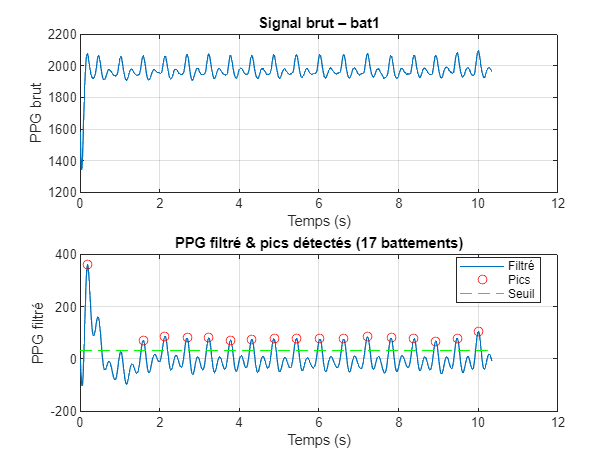

%% 1) Construction de l’axe temporel
fs = 500/7;                           % Fréquence d’échantillonnage (Hz) → à adapter
N  = length(bat);
t  = (0:N-1)/fs;                  % Temps en secondes

%% 2) Filtrage passe‑bande (0,5–5 Hz)
f_low  = 0.5;                     
f_high = 5;
ordre  = 3;
Wn     = [f_low f_high]/(fs/2);
[b,a]  = butter(ordre, Wn, 'bandpass');
ppg_filt = filtfilt(b, a, bat);

%% 3) Détection des pics (battements)
seuil     = mean(ppg_filt) + 0.5*std(ppg_filt);
minDist   = 0.4;                   % en secondes (150 bpm max)
[peaks, locs] = findpeaks(ppg_filt, t, ...
    'MinPeakHeight', seuil, ...
    'MinPeakDistance', minDist);

nb_battements = numel(peaks);

%% 4) Calcul de la Fréquence Cardiaque Instantanée
IBI      = diff(locs);             % Inter‑beat intervals (s)
HR_inst  = 60 ./ IBI;              % bpm
t_HR     = locs(2:end);

%% 5) Affichages

% Signal brut vs signal filtré
figure;
subplot(2,1,1);
plot(t, bat);
xlabel('Temps (s)'); ylabel('PPG brut');
title('Signal brut – bat1'); grid on;

subplot(2,1,2);
plot(t, ppg_filt);
hold on;
plot(locs, peaks, 'ro');
plot(t, seuil*ones(size(t)), '--g');
xlabel('Temps (s)'); ylabel('PPG filtré');
title(['PPG filtré & pics détectés (',num2str(nb_battements),' battements)']);
legend('Filtré','Pics','Seuil','Location','best');
grid on;

**Fréquence cardiaque instantanée** : La deuxième figure trace l'évolution temporelle de la fréquence cardiaque instantanée. Ce graphique permet d'observer les variations de la fréquence cardiaque au cours du temps et d'identifier d'éventuelles arythmies ou variations physiologiques. Les points reliés par des lignes facilitent la lecture des tendances. Plus cette valeur tend vers une constante, plus les battements sont réguliers, ce qui témoigne d’une bonne qualité de signal et d’un rythme cardiaque stable.

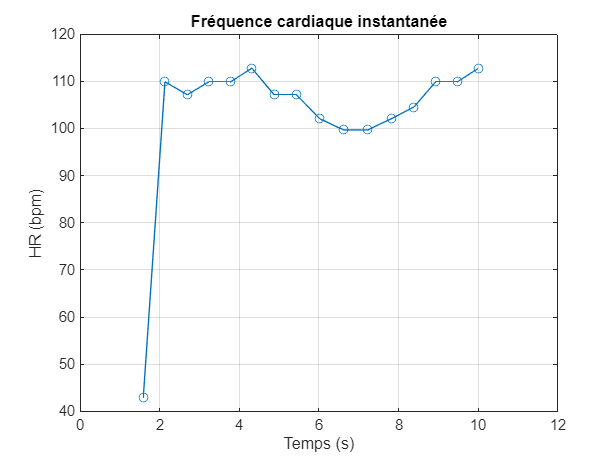

% Fréquence cardiaque instantanée
figure;
plot(t_HR, HR_inst, '-o');
xlabel('Temps (s)'); ylabel('HR (bpm)');
title('Fréquence cardiaque instantanée');
grid on;

**Statistiques globales** : Cette section calcule et affiche les statistiques descriptives de la fréquence cardiaque : moyenne, minimum et maximum. Ces valeurs fournissent un résumé quantitatif de l'état cardiaque pendant la période d'enregistrement et permettent une évaluation rapide de la variabilité de la fréquence cardiaque. L'affichage formaté dans la console MATLAB présente ces informations de manière claire et structurée.



% Statistiques globales
HR_moy = mean(HR_inst);
HR_min = min(HR_inst);
HR_max = max(HR_inst);

fprintf('\n=== Statistiques Fréquence Cardiaque ===\n');


=== Statistiques Fréquence Cardiaque ===


fprintf('Moyenne : %.1f bpm\n', HR_moy);

Moyenne : 103.0 bpm


fprintf('Min     : %.1f bpm\n', HR_min);

Min     : 42.9 bpm


fprintf('Max     : %.1f bpm\n', HR_max);

Max     : 112.8 bpm
